clear all

% 3.1
data = importdata("Assignment_Data_SC42145_2022.mat");
WindData=data.WindData;
FWT=data.FWT;
G=[FWT(1,1) FWT(1,2)];
Gd = FWT(1,3);
s = tf('s');

% 3.2
wB1=0.1*2*pi; % desired closed-loop bandwidth
A=1/1000 % desired disturbance attenuation inside bandwidth

A = 1.0000e-03

M=3 ; % desired bound on hinfnorm(S)
Wp11=(((s/sqrt(M))+wB1)^2)/((s+(wB1*sqrt(A)))^2)

Wp11 =
 
     s^2 + 2.177 s + 1.184
  ---------------------------
  3 s^2 + 0.1192 s + 0.001184
 
Continuous-time transfer function.




Wp=[Wp11]; %

% 3.3

tau11= 0.1;
k1 = 10000;
a1 = 0.1;

Wu11 = a1*((k1*tau11*s+1)/(tau11*s+1)) %lead lag filter

Wu11 =
 
  100 s + 0.1
  -----------
   0.1 s + 1
 
Continuous-time transfer function.




tau22 = 1000;
k2 = 0.0000001;
a2=0.0001

a2 = 1.0000e-04


Wu22 = a2*(1/k2)*((tau22*k2*s+1)/(tau22*s+1))  %lead lag filter

Wu22 =
 
  0.1 s + 1000
  ------------
   1000 s + 1
 
Continuous-time transfer function.




Wu=[Wu11 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []



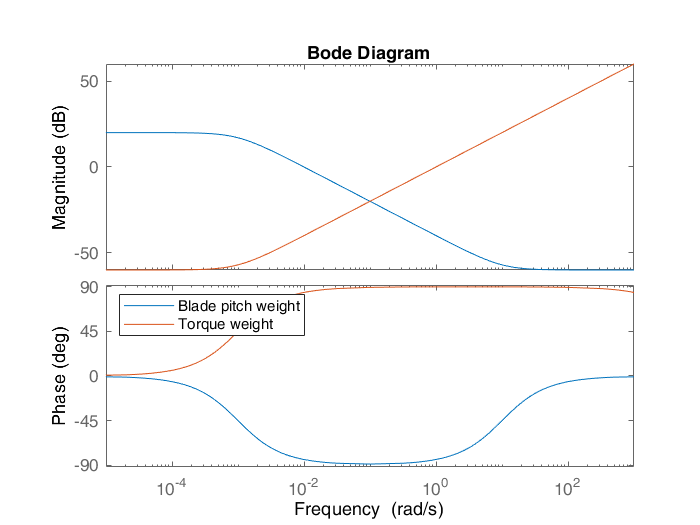


bode(1/Wu11,1/Wu22)
legend('Blade pitch weight','Torque weight','location','northwest')

% 3.4
P11=Wp*Gd;
P12=Wp*-G;
P21=[0;0];
P22=Wu;
P31=Gd;
P32=-G;

P=[P11 P12; P21 P22;P31 P32];
[K,CL,GAM,INFO] = hinfsyn(P,1,2);
CL=minreal(CL);

36 states removed.


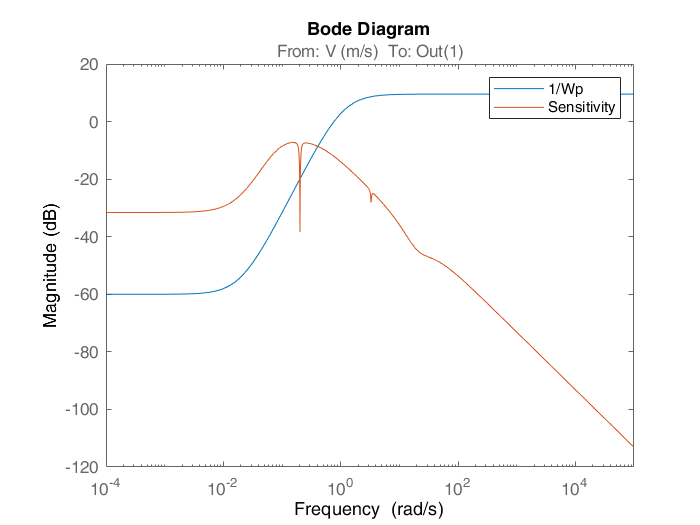


Sens=(1/Wp)*CL(1);
KS1=(1/(Wu11))*CL(2);
KS2=(1/(Wu22))*CL(3);

figure()
bodemag(1/Wp,Sens)
legend('1/Wp', 'Sensitivity')

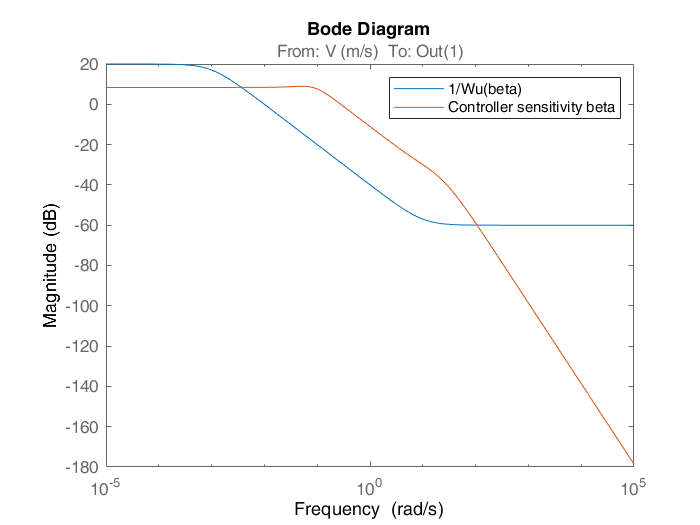


figure()
bodemag(1/Wu11,KS1)
legend('1/Wu(beta)', 'Controller sensitivity beta')

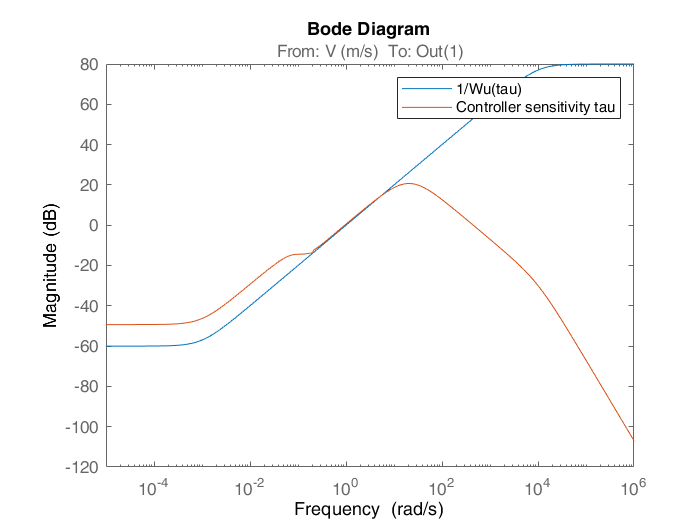


figure()
bodemag(1/Wu22,KS2)
legend('1/Wu(tau)', 'Controller sensitivity tau')

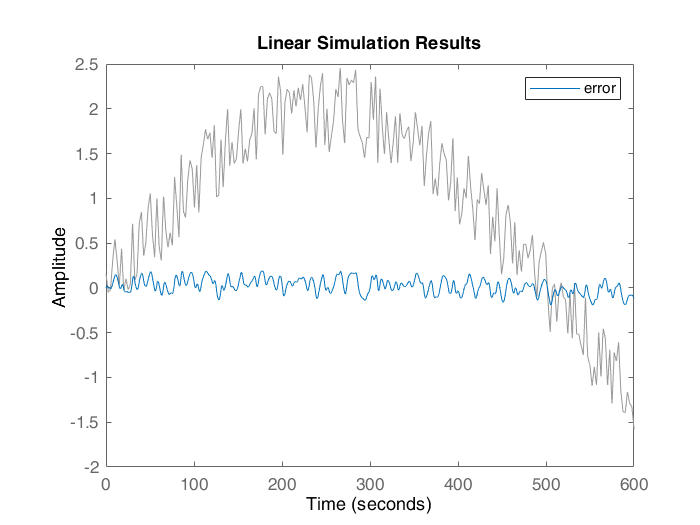

% 3.5
time = WindData(:,1);
input = WindData(:,2);

figure()
lsim(Sens,input,time)
legend('error')

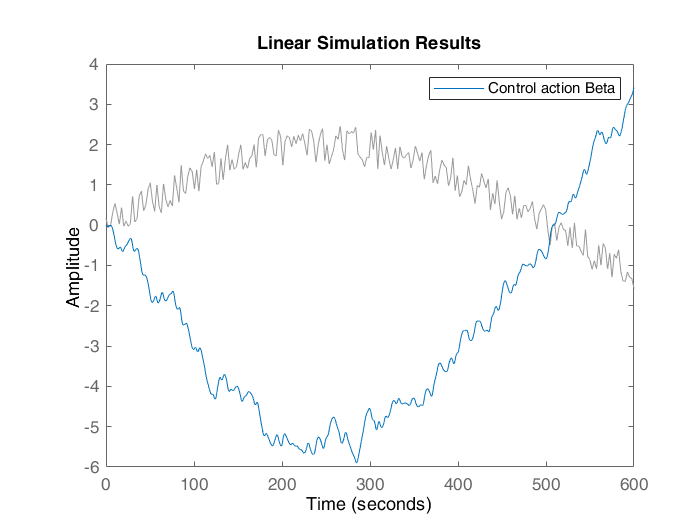


figure()
lsim(KS1,input,time)
legend('Control action Beta')

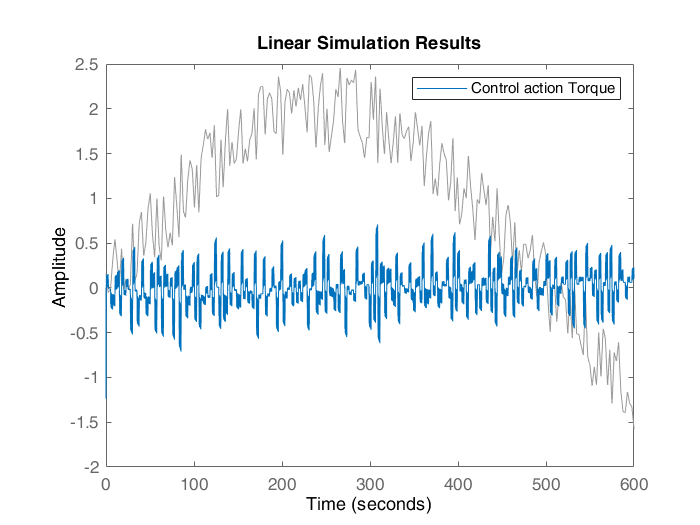


figure()
lsim(KS2,input,time)
legend('Control action Torque')

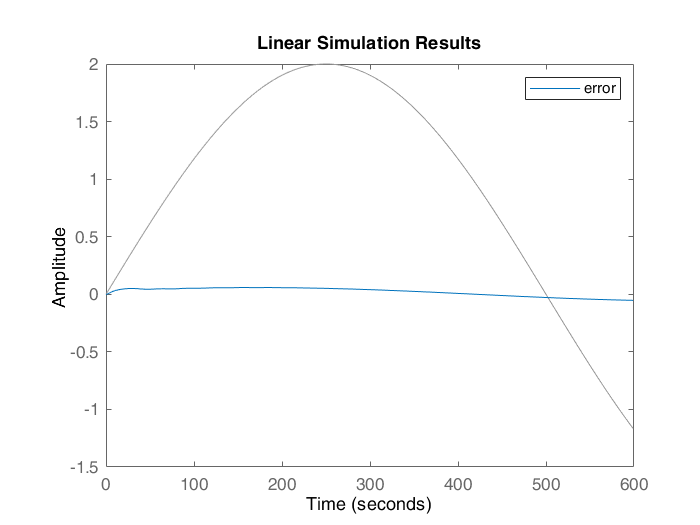


time1 = linspace(0,599,600);
input1 = 2*sin(2*pi*time1/1000);

figure()
lsim(Sens,input1,time1)
legend('error')

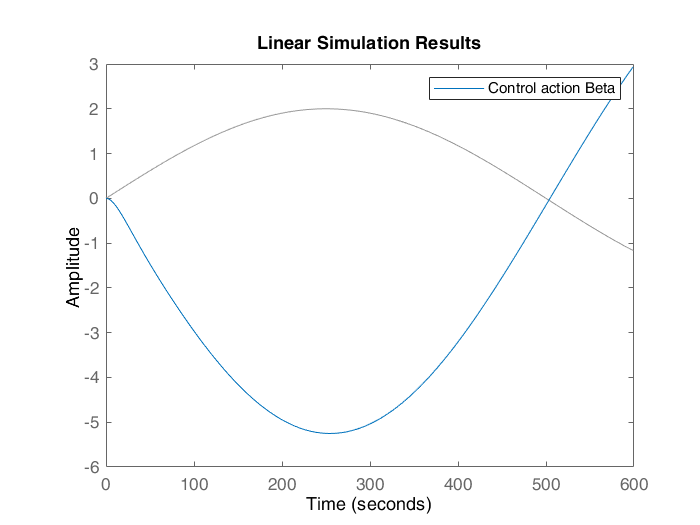


figure()
lsim(KS1,input1,time1)
legend('Control action Beta')

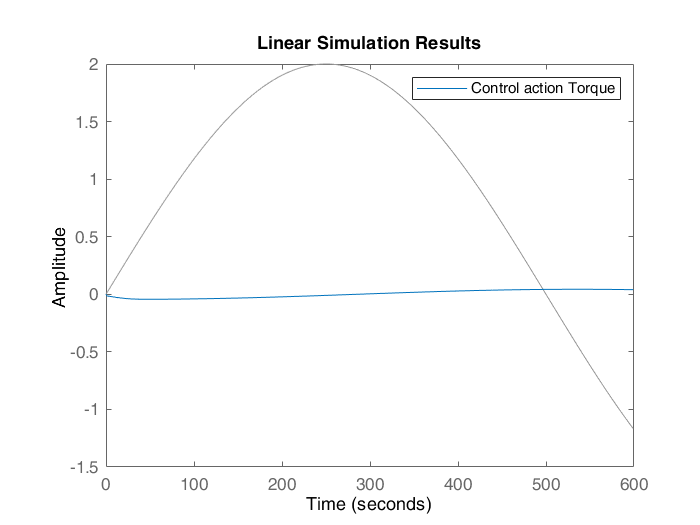


figure()
lsim(KS2,input1,time1)
legend('Control action Torque')